clear 
num_c = 30;  % number of cars 

% Initial Conditions 
% Note: The index of the car corresponds to the order of the car. (Ex: Car 1
% is in the first element of the vector)
pos_0 = linspace(200, 40, num_c); % Initial position of cars.
vel_0 = zeros(1,num_c); % Initial velocity of cars. 
acc_0 = zeros(1,num_c); % Inital acceleration of cars.

% Characteristic of cars and road. 
lengths = ones(1,num_c)*5; % Length of cars. 
gamma = 0.6; % Speed difference sensitivity. 
x_destination = 2000; % Destination.
maxLane = 1;
b_safe = 2;
delta_a = 0.1;
a_bias = 0.3;

% Parameters for Numerical Integration
tstep = .01;
t_final = 120;
numsteps = round(t_final/tstep);

% Default initialize an array and set parameters for the vehicles. 
vehiclesInOrder(1:num_c) = Vehicle(); 
for i = 1:num_c
    vehiclesInOrder(i) = Vehicle(i, pos_0(i), vel_0(i), acc_0(i), 1, lengths(i), false);
end

% Traffic Lights
tlArr = [Vehicle(num_c + 1, 1000, 0, 0, -1, 0, true), Vehicle(num_c + 2, 1000, 0, 0, -2, 0, true)];
num_c = num_c + length(tlArr);
vehiclesInOrder = [vehiclesInOrder, tlArr];
vehiclesInOrder = Vehicle.sortCars(vehiclesInOrder);

% Create array to store time, position, velocity, acceleration, and gap.
tvals = linspace(0, t_final, numsteps);
xvals = zeros(numsteps, num_c);
vvals = zeros(numsteps, num_c);
avals = zeros(numsteps, num_c);
gvals = zeros(numsteps, num_c);
lanevals = zeros(numsteps, num_c);


for t = 1:numsteps
    for i = num_c:-1:1 % Loop through the car starting with the last car.
        if ~vehiclesInOrder(i).isTrafficLight
            laneNum = vehiclesInOrder(i).lane;
            [v_l, s, ~, ~] = Vehicle.findGaps(vehiclesInOrder, i, laneNum, x_destination);

            % Compute gap and state variables.
            newstate = vehiclesInOrder(i).timestep(s, v_l, tstep, gamma);
            v_num = vehiclesInOrder(i).number;
            gvals(t, v_num) = s;
            xvals(t, v_num) = newstate(1);
            vvals(t, v_num) = newstate(2);
            avals(t, v_num) = newstate(3);
            lanevals(t, v_num) = vehiclesInOrder(i).lane;
            
            % lane change
            % newlane = vehiclesInOrder(i).changeLane(i, vehiclesInOrder, maxLane, b_safe, delta_a, a_bias, gamma, x_destination);
            
        else
            %It is a traffic light
            v_num = vehiclesInOrder(i).number;
            xvals(t, v_num) = vehiclesInOrder(i).state(1);

        end
              
    end
    
    if t == .20*numsteps || t == .50*numsteps
        for i = 1:num_c
            if vehiclesInOrder(i).isTrafficLight
                tl_lane = vehiclesInOrder(i).lane;
                vehiclesInOrder(i).lane = -1*tl_lane;
            end
        end
    end
        
    vehiclesInOrder = Vehicle.sortCars(vehiclesInOrder);
end

xvals = xvals(:,1:30);
vvals = vvals(:,1:30);
avals = avals(:,1:30);
gvals = gvals(:,1:30);

% Build colormap 
cmap = (1/256) .*[0, 0, 0;
        105, 105, 105;
        211, 211, 211;
        85, 107, 47;
        139, 69, 19;
        34, 139, 34;
        72, 61, 139;
        184, 134, 11;
        0, 139, 139;
        70, 130, 180;
        0, 0, 128;
        154, 205, 50;
        143, 188, 143;
        139, 0, 139;
        176, 48, 96;
        255, 69, 0;
        255, 215, 0;
        124, 252, 0;
        138, 43, 226;
        0, 255, 127;
        220, 20, 60;
        0, 255, 255;
        0, 0, 255;
        255, 0, 255;
        30, 144, 255;
        240, 230, 140;
        144, 238, 144;
        255, 20, 147;
        255, 160, 122;
        238, 130, 238]

cmap =          0         0         0
    0.4102    0.4102    0.4102
    0.8242    0.8242    0.8242
    0.3320    0.4180    0.1836
    0.5430    0.2695    0.0742
    0.1328    0.5430    0.1328
    0.2812    0.2383    0.5430
    0.7188    0.5234    0.0430
         0    0.5430    0.5430
    0.2734    0.5078    0.7031


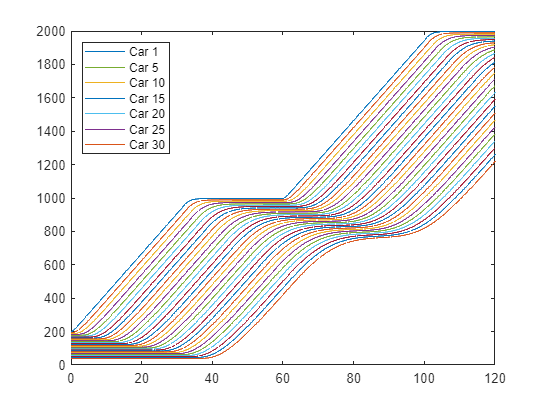

% Set colororder and plot
ax1 = axes('colororder',cmap);

% Graph position versus time. 
for i = 1:num_c - 2
    j(i) = plot(tvals, xvals(:,i));
    hold on;
end
legend([j(1) j(5) j(10) j(15) j(20) j(25) j(30)], 'Car 1', 'Car 5', 'Car 10', 'Car 15', 'Car 20', 'Car 25', 'Car 30', 'Location', 'northwest');
hold off;

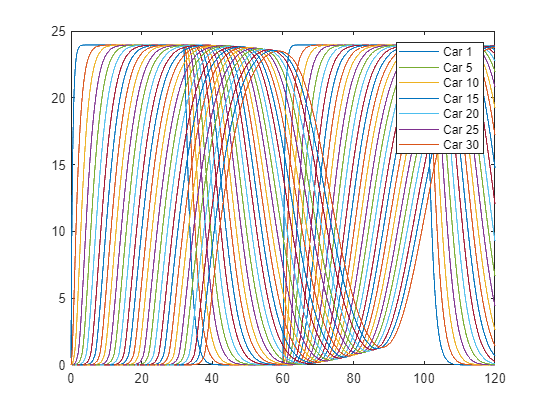


% Graph velocity versus time.
for i = 1:num_c - 2
    h(i) = plot(tvals, vvals(:,i));
    hold on;
end
legend([h(1) h(5) h(10) h(15) h(20) h(25) h(30)], 'Car 1', 'Car 5', 'Car 10', 'Car 15', 'Car 20', 'Car 25', 'Car 30');
hold off;

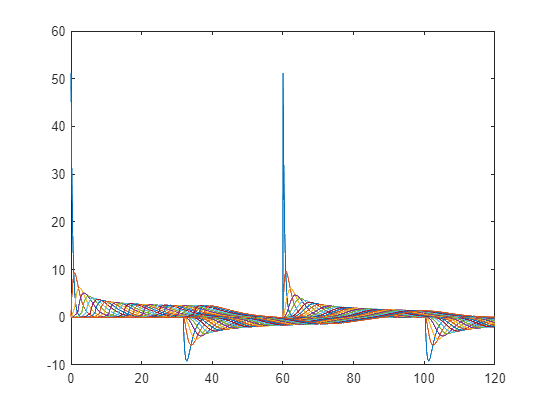


% Graph acceleration versus time.
for i = 1:num_c - 2
    plot(tvals, avals(:,i))
    hold on;
end
hold off;

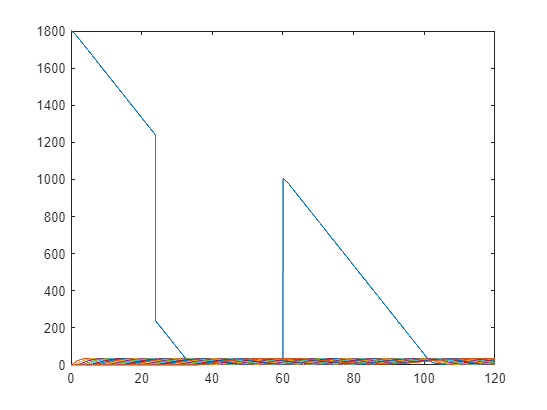


% Graph gap versus time.
for i = 1:num_c - 2
    plot(tvals, gvals(:,i))
    hold on;
end
hold off

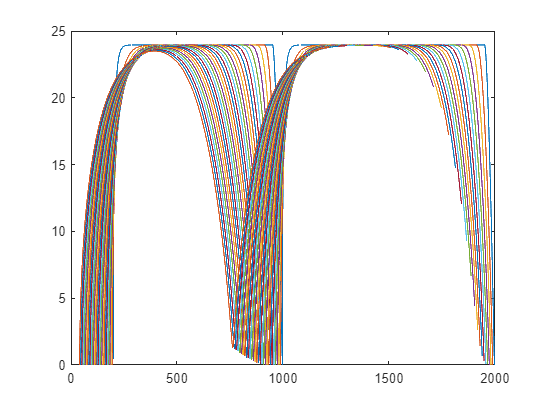


% Graph velocity versus position.
for i = 1:num_c - 2
    plot(xvals(:,i), vvals(:,i))
    hold on;
end
hold off

Finding density

time = 1:12000;
time = time./100;
density = zeros(10000,99);
delta_x = linspace(0,x_destination,100);
for i=1:12000
    for j=1:99
        carDensity = length(find(xvals(i,:) > delta_x(j) & xvals(i,:) < delta_x(j+1)));
        density(i,j) = carDensity;
    end
end
dist = linspace(0,x_destination,99);
density = transpose(density);
colormap('hot');         % set colormap

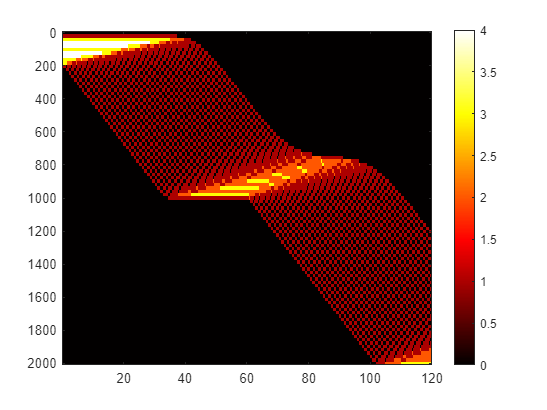

imagesc(time,dist,density);        % draw image and scale colormap to values range
colorbar;